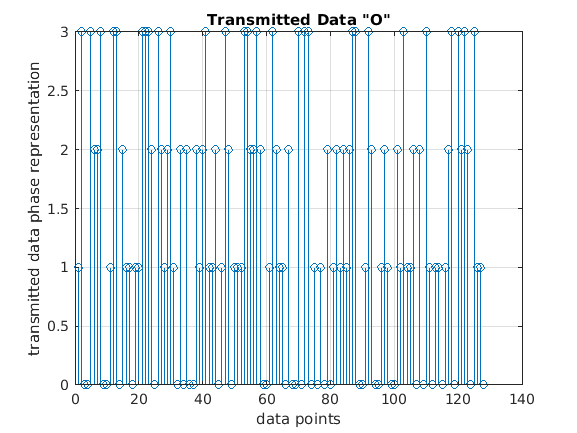

clc;
clear all;
close all;


M = 4;                 % Modulation QPSK constillation 
k = log2(M);           % Bits/symbol
numSC = 32;            % Number of OFDM subcarriers DATA
cpLen = 32;            % OFDM cyclic prefix length
no_of_ifft_points = 8;           %   8 points for the FFT/IFFT
no_of_fft_points = 8;

%1.setting a QPSK modulator and demodulator so that they accept binary inputs.
input_data=randsrc(1,numSC*4,0:M-1);
figure   
stem(input_data);xlabel('data points');ylabel('transmitted data phase representation');title('Transmitted Data "O"');grid on

%2.QPSK modulation of the DATA 
QPSK=pskmod(input_data,M)

QPSK =    0.0000 + 1.0000i  -0.0000 - 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i


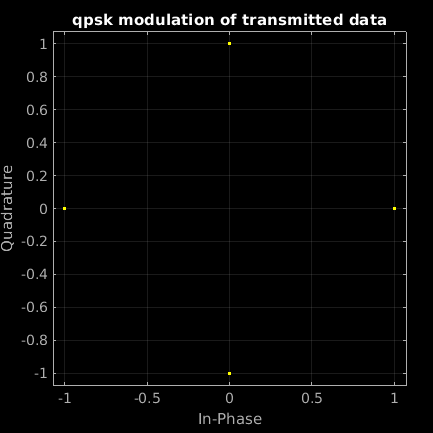

figure , scatterplot(QPSK);title('qpsk modulation of transmitted data');grid on

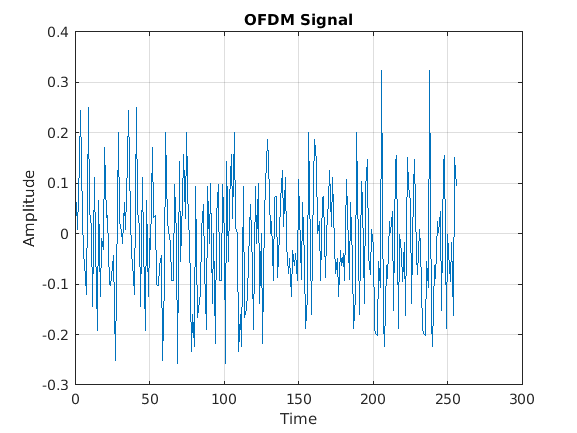

%3.Doing IFFT on each block Make the serial stream a matrix where each column represents a pre-OFDM block (w/o cyclic prefixing)
% First: Find out the number of colums that will exist after reshaping
col=length(QPSK)/numSC;
data = reshape(QPSK,numSC,col);
% Second: to create empty matix to put the IFFT data
cp_start =numSC-cpLen;
cp_end = numSC;
% Third: Operate column wise & do CP
for i=1:col
    ifft_data_matrix(:,i) = ifft((data(:,i)),cpLen);
    %   Compute and append Cyclic Prefix
    for j=1:cpLen
       actual_cp(j,i) = ifft_data_matrix(j+cp_start,i);
    end
    %   Append the CP to the existing block to create the actual OFDM block
       ifft_data(:,i) = vertcat(actual_cp(:,i),ifft_data_matrix(:,i));
end
%4.Convert to serial stream for transmission
[rows_ifft_data, cols_ifft_data]=size(ifft_data);
len_ofdm_data = rows_ifft_data*cols_ifft_data;
%   Actual OFDM signal to be transmitted
ofdm_signal = reshape(ifft_data, 1, len_ofdm_data);
figure
plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');title('OFDM Signal');grid on;

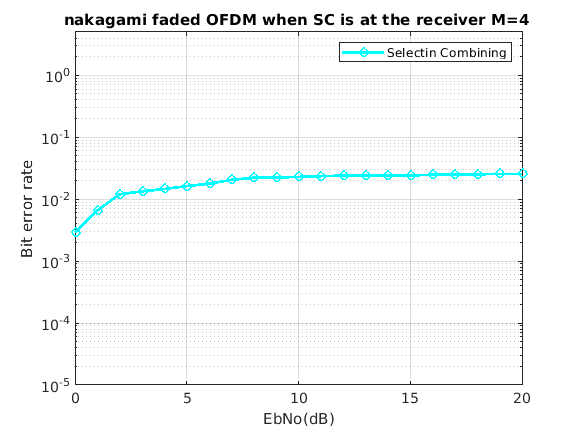


%%Nakagami Fading on channels
pd= makedist('Nakagami','mu',9,'omega',3);
naka1=random(pd,256,1);
naka2=random(pd,256,1);
mod_fa=abs(ofdm_signal).*naka1;
mod_fa=mod_fa/max(mod_fa);
mod_fa2=abs(ofdm_signal).*naka2;
mod_fa2=mod_fa2/max(mod_fa2);


%%At receiever selection combining


x = 1; % signal to transmit Eb = 1
T = 10000; %number of simulation runs per EbN0 %50000
N=10^6;
SC_Branch=[];
err=0;
for snr = 0:1:35 %dB
    lnear_snr= 10^(snr/10); 
    E_b = 1/(lnear_snr); 
        for t = 1:T %  count the errors
            awgn_noise  = sqrt(E_b/2)*randn*mod_fa; 
            awgn_noise_2 =sqrt(E_b/2)*randn*mod_fa2;
             %Selection combining
            P1 = exprnd(5);
            P2 = exprnd(5);
            
            amp_1 = P1*(abs(mod_fa)).^2;
            amp_2 = P2*(abs(mod_fa2)).^2;
            if amp_1 >= amp_2
                SC_Branch = x.*(amp_1)+awgn_noise;
            end
            if amp_1 < amp_2
                SC_Branch = x.*(amp_2)+awgn_noise_2;
            end
            if SC_Branch < 0 
               err = err+ 1;
            end
        end
    
    BER(snr+1) = err/(T);
end

% plot simulations
figure
snr=0:1:35; %changed from 10
semilogy(snr,BER,'c-o',"LineWidth",2); % plot EG BER vs EbNo
hold on;
grid on;
axis([0 20 10^-5 5])
legend('Selectin Combining');
xlabel('EbNo(dB)') %Label for x-axis
ylabel('Bit error rate') %Label for y-axis
title('nakagami faded OFDM when SC is at the receiver M=4 ');






%%%%%%%%%%%%Outage probability of nakagami faded OFDM Signal %%%%%%%%
snr=0:1:35;
gamma = 5;
gambar2=[];
gambar1=[]


gambar1 =

     []



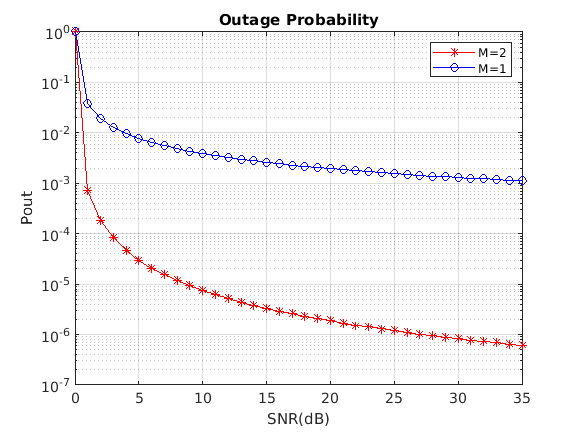

A= size(mod_fa);
for k=1:A(2)
    n_a3=mod_fa(:,k);
    n_b3=mod_fa2(:,k);
    gam1=0;
    gam2=0;
for i=1:length(mod_fa2)
    sc_seq=(abs(n_a3(i))^2)+(abs(n_b3(i))^2)/2;
    gam1=gam1+sc_seq;
    gam2=gam2+abs(n_a3(i)^2);
end
gambar2=[gambar2,gam1];
gambar1=[gambar1,gam2];
end
gambar1=gambar1.*snr;
gambar2=gambar2.*snr;
gamma1 = gamma./(gambar2);
gamma2 = gamma./(gambar1);
for i = 1:length(gamma1)
    Po_1(i)=(1-exp(-(gamma/gambar1(i))));
    Po_2(i)=(1-exp(-(gamma/gambar2(i))))^2;
end
figure()
semilogy(snr,Po_2,'r*-');hold on;
semilogy(snr,Po_1,'b-o');
grid on;
xlabel('SNR(dB)');
ylabel('Pout');
legend('M=2','M=1');
title('Outage Probability')